# Group Assignment

SID: 480564906, XXX, XXX

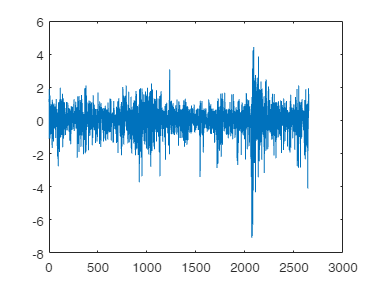

tbl = readtable("AORD_2012_2022.xlsx");
% Centering the returns
returns = tbl.Return - mean(tbl.Return);
y = returns;

plot(y)

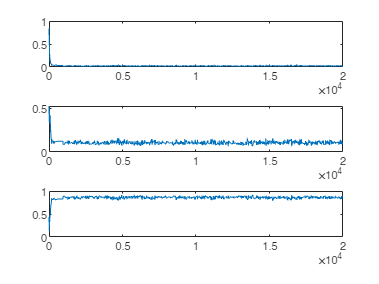

ans =     0.0242    0.1064    0.8600



rng(3830)

perform_RWMH(20000,y,eye(3)/100000,1,1,0)

function joint_prior = get_joint(phi)
    alpha = phi(2);
    beta = phi(3);
    gamma_part = gamma(11.5)/(gamma(10)*gamma(1.5));
    alpha_part = (alpha^0.5)*((1-alpha)^9);
    beta_part = (beta^9)*((1-beta)^0.5);
    joint_prior = (gamma_part^2)*alpha_part*beta_part;
end
    

function sigma2 = get_sigma2(y,phi)
    omega=phi(1);
    alpha=phi(2);
    beta=phi(3);

    T = length(y);
    sigma2 = zeros(T,1);
    
    for t=1:T
        if t==1
            sigma2(t) = var(y); 
        else    
            sigma2(t) = omega+(alpha*(y(t-1)^2))+beta*(sigma2(t-1));
        end   
    end
    
end

function llh = group_log_likelihood(y,sigma2)
    summation = sum(log(2*pi)+log(sigma2)+((y.^2)./sigma2));
    llh = -0.5*summation;
end


%function alpha = calc_alpha(theta2,theta3)
%alpha = (exp(theta2)*exp(theta3))/(1+exp(theta2)+exp(theta3)+exp(theta2)*exp(theta3));
%end

%function beta = calc_beta(theta2,theta3)
%beta = exp(theta2)/(1+exp(theta2)+exp(theta3)+exp(theta2)*exp(theta3));
%end


function mean_phis = perform_RWMH(Niter,y,RWMH_Sigma,plots,adaptive,means_stds)
dim = 3; % the dimension of phis

markov_chain = zeros(Niter,dim); 
%we have to make our starting phi0 be valid:
while 1
    phi0 = rand(1,dim); % starting value for our omega,alpha,betas
    if phi0(1)>0 && phi0(2)>0 && phi0(3)>0 && (phi0(2)+phi0(3))<1
        break
    end
end

markov_chain(1,:) = phi0;
current_sigma2 = get_sigma2(y,markov_chain(1,:));

i = 1;
while i<Niter
    %if I want to use the adaptive RWMH_Sigma
    if adaptive==1 && i<=1000
        RWMH_Sigma=((0.1^2)/dim)*eye(dim); 
    elseif adaptive==1 && i>1000
        RWMH_Sigma = 0.05*((0.1^2)/dim)*eye(dim) +(1-0.05)*((2.38^2)/dim)*cov(markov_chain(i-1000:i,:));% update RWMH_Sigma based on the last 1000 iterations
    else
        ; %just keep RWMH_Sigma as provided, not adaptive.
    end
    %ok lets make our proposal
    while 1
        epsilon = mvnrnd(zeros(3,1),RWMH_Sigma);
        proposal = markov_chain(i,:)+epsilon;
        if round(proposal(1),4)>0 && round(proposal(2),4)>0 && round(proposal(3),4)>0 && (proposal(2)+proposal(3))<1
            break
        end
    end
    proposal_sigma2 = get_sigma2(y,proposal);

    %rejection/acceptance
    aux_proposal =group_log_likelihood(y,proposal_sigma2)+log(get_joint(proposal));
    aux_current = group_log_likelihood(y,current_sigma2)+log(get_joint(markov_chain(i,:)));
    auxiliary =aux_proposal-aux_current;
    
    rejection_threshold = min(exp(auxiliary),1);
    u = rand;
    if u<rejection_threshold && proposal(1)>0 && proposal(2)>0 && proposal(3)>0 && (proposal(2)+proposal(3))<1
        %naive checking satisfactory proposal
        markov_chain(i+1,:) = proposal;
        current_sigma2 = proposal_sigma2;
    else
        markov_chain(i+1,:) = markov_chain(i,:);
    end
    i = i+1;
end
%if i want to make traceplots
if plots==1
    subplot(3,1,1)
    plot(markov_chain(:,1))
    subplot(3,1,2)
    plot(markov_chain(:,2))
    subplot(3,1,3)
    plot(markov_chain(:,3))
end

%toss burn-in period (rows 0 to 1000)
mean_phis = transpose([mean(markov_chain(1000:Niter,1))
    mean(markov_chain(1000:Niter,2))
    mean(markov_chain(1000:Niter,3))]);
%if i also want to return the standard deviations for each ß
if means_stds==1
    std_phis= transpose([std(markov_chain(1000:Niter,1))
    std(markov_chain(1000:Niter,2))
    std(markov_chain(1000:Niter,3))]);
    mean_phis = [mean_phis;std_phis]; %return a list
end

end
